close all
clear
clc

定义系统

a = 0.8;
N = 6;

生成仿真时刻n、截断的单位样值响应和完整的激励序列

n = [0:20]';
h = (a.^n);
x = (n>=0&n<N);

默认方法：直接卷积

yc = conv(h, x);

另一种方法：以x为激励，以h和1分别为系统的b和a系数，用滤波计算

yf1 = filter(h, 1, x);

另二种方法：以h为激励，以x和1分别为系统的b和a系数，用滤波计算

yf2 = filter(x, 1, h);

另三种方法：以x为激励，以1和[1,-a]分别为系统的b和a系数，用滤波计算

yf3 = filter(1,[1, -a], x);

计算另外几种方法的差异非常小

disp('误差分别为');

误差分别为


disp(sum(abs([yf1-yf2,yf1-yf3,yf2-yf3])));

   1.0e-14 *
    0.2831    0.1860    0.1082


绘图

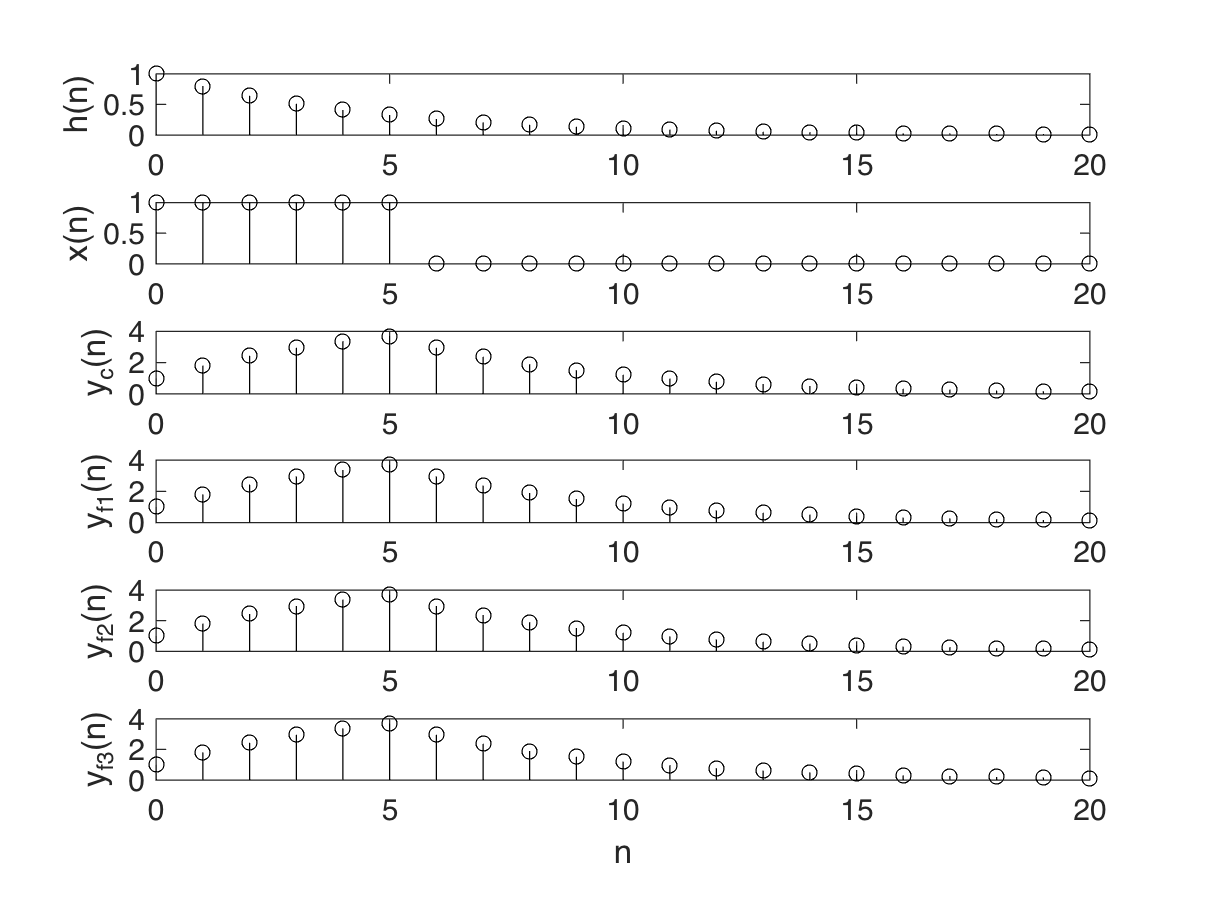

ftsz = 12;
figure;
data = {h,x,yc(1:length(n)),yf1,yf2,yf3};
labels = {'h(n)';'x(n)';'y_c(n)';'y_{f1}(n)';'y_{f2}(n)';'y_{f3}(n)'};
for k = 1:6
    subplot(6,1,k), hold on, box on;
    stem(n,data{k},'k-'); 
    set(gca,'FontSize',12);
    ylabel(labels{k});
end
xlabel('n');